## Traits are strings

Companion file analyzing the case where traits are represented as finite strings on a finite alphabet, which affects how mutation occurs. 

clear; clc;
close all % closes open figures

## Spread Functions 

Here we define different possible spread functions on the hypercube. 

cube_1 = @(u) (1-u)*ones(1,8) + u * ...
    [[0 1 1 1 0 0 0 0]; 
     [1 0 0 0 1 1 0 0]; 
     [1 0 0 0 1 0 1 0]; 
     [1 0 0 0 0 1 1 0]; 
     [0 1 1 0 0 0 0 1]; 
     [0 1 0 1 0 0 0 1]; 
     [0 0 1 1 0 0 0 1]; 
     [0 0 0 0 1 1 1 0]];

cube_adj = @(num_let,str_len,u) (1-u)*eye(num_let^str_len) + ...
    u*cube_spread(num_let,str_len,u,@(u,dist) dist == 1);
cube_all = @(num_let,str_len,u) cube_spread(num_let,str_len,u, ...
    @(u,dist) u^dist * (1-u)^(num_let^str_len-dist));
cube_unif = @(num_let,str_len,u) cube_spread(num_let,str_len,u, ...
    @(u,dist) (u/num_let)^dist * (1-u+u/num_let)^(num_let^str_len-dist));
cube_dif = @(num_let,str_len,u) cube_spread(num_let,str_len,u, ...
    @(u,dist) (u/(num_let-1))^dist * (1-u)^(num_let^str_len-dist));
triangle = @(u) [[1-u u/2 u/2];
                 [u/2 1-u u/2];
                 [u/2 u/2 1-u]]; % walk on triangle

##  Computing Max Eigs and Stable Distributions

Inputs: the number of letters in the alphabet, length of a string representing a trait, and an array giving the fitness of each trait. 

num_let = 2;
str_len = 2;
fitness = [2, 1, 1, 1];
words = gen_words(num_let,str_len);

us = 0.01*(1:99); % u can't be 0 or 1 for cube_all, as 
% then all entries will be zero

tic
max_eigs = zeros(1,length(us));
stable_dists = zeros(length(us), num_let^str_len);
growth = diag(fitness);
for k=1:length(us)
    spread = cube_all(num_let,str_len,us(k));
    A = spread*growth;
    [V,D] = eig(A);
    [max_eig, loc] = max(diag(D));
    max_eigs(k) = max_eig;
    stable_dist = abs(V(:,loc))/sum(abs(V(:,loc)));
    stable_dists(k,:) = stable_dist;
end
toc

Elapsed time is 0.179714 seconds.


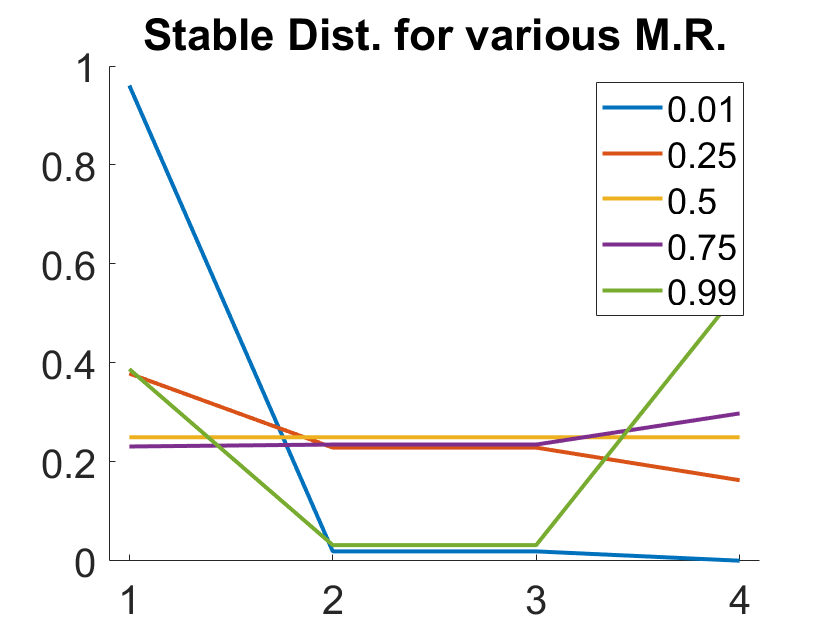


is = [1,25, 50, 75, 99];
colors = ['+', '_', '.', '|', 'x'];
%colors = ['-s', '_', '.', '|', '-o'];
figure
hold on
marker_size = 10;
traits = 1:4; %["00", "01", "10", "11"];
plot(traits, stable_dists(is(1),:), '-','MarkerSize',marker_size, "LineWidth",2);
plot(traits, stable_dists(is(2),:), '-','MarkerSize',marker_size, "LineWidth",2);
plot(traits, stable_dists(is(3),:), '-','MarkerSize',marker_size, "LineWidth",2);
plot(traits, stable_dists(is(4),:), '-','MarkerSize',marker_size, "LineWidth",2);
plot(traits, stable_dists(is(5),:), '-','MarkerSize',marker_size, "LineWidth",2);
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
set(gca,"FontSize",20)
xlim([0.9,4.1])
hold off
title("Stable Dist. for various M.R.")

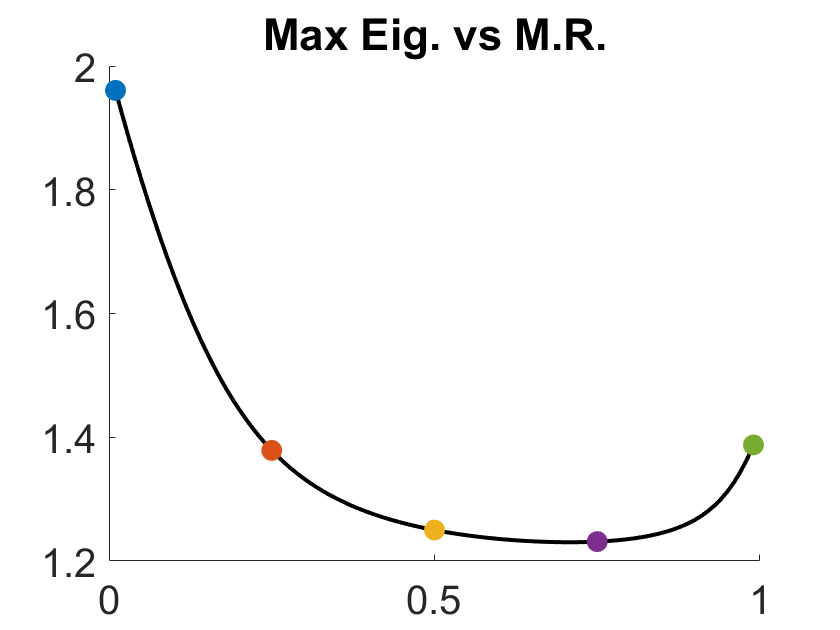


figure
hold on
plot(us, max_eigs, 'k', 'LineWidth',2)
marker_size = 10;
colors = [[     0 0.4470 0.7410];
          [0.8500 0.3250 0.0980];
          [0.9290 0.6940 0.1250];
          [0.4940 0.1840 0.5560];
          [0.4660 0.6740 0.1880]];
plot(us(1),  max_eigs(1),  'o', ...
    'MarkerFaceColor', colors(1,:), 'MarkerEdgeColor', colors(1,:), 'MarkerSize', marker_size)
plot(us(25), max_eigs(25), 'o', ...
    'MarkerFaceColor', colors(2,:), 'MarkerEdgeColor', colors(2,:), 'MarkerSize', marker_size)
plot(us(50), max_eigs(50), 'o', ...
    'MarkerFaceColor', colors(3,:), 'MarkerEdgeColor', colors(3,:), 'MarkerSize', marker_size)
plot(us(75), max_eigs(75), 'o', ...
    'MarkerFaceColor', colors(4,:), 'MarkerEdgeColor', colors(4,:), 'MarkerSize', marker_size)
plot(us(99), max_eigs(99), 'o', ...
    'MarkerFaceColor', colors(5,:), 'MarkerEdgeColor', colors(5,:), 'MarkerSize', marker_size)
title("Max Eig. vs M.R.")
set(gca,"FontSize",20)
hold off

function spread = cube_spread(num_let,str_len,u,f)
    n = num_let^str_len;
    spread = zeros(n,n);
    for i=0:(n-1)
        for j=0:(n-1)
            dist = sum(pad(dec2base(i,num_let),str_len,'left','0') ...
                    ~= pad(dec2base(j,num_let),str_len,'left','0'));
            spread(i+1,j+1) = f(u,dist);
        end
        spread(i+1,:) = spread(i+1,:) / sum(spread(i+1,:));
    end
    spread = spread';
end

function words = gen_words(num_let,str_len)
    n = num_let^str_len;
    words = cell(1,n);
    for i=0:(n-1)
        words(i+1) = {pad(dec2base(i,num_let),str_len,'left','0')};
    end
end